# Temperature Profile of a Vertical Ice Column

## Introduction

In order to describe the temperature profile of an ice sheet, glacier, or ice shelf, the heat exchange within a 1-D vertical column of ice can be modeled using advection-diffusion. The premise is that, as the ice shifts vertically (advection), the temperature gradient will change (diffusion).

Various numerical models have been used, with different physical phenomena considered. To describe the ice column, some of these phenomena can be included or omitted. A study by Moreno-Parada et al. (2024) included numerical solutions that involved multiple combinations of diffusion, vertical and horizontal advection, and strain heating. Another study assumed that horizontal advection and diffusion of heat are small enough to be negligible (Rezvanbehbahani et al., 2019). Methods employed in other studies include oxygen isotope profiles as a record of temperature variation (Robin, 1973), strain heating and creep instability (Clarke et al., 1977), and one including snow accumulation (Robin, 1955).

This model will use the advection-diffusion equation with multiple heat sources to solve the temperature profile of an ice sheet as it varies in time.

## Equations

As described, the main mechanism for heat transfer is advection and diffusion of ice vertically along the length of the column, and horizontally between other columns.

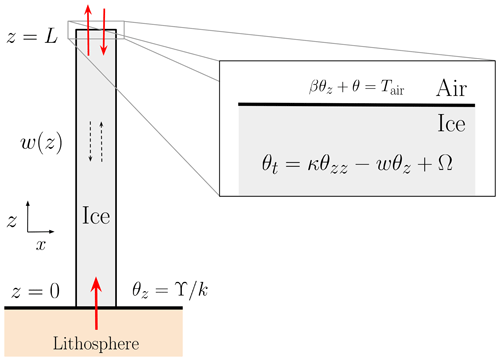

This illustration by Moreno-Parada et al. shows the setup for the problem, and various parameters that must be considered.

We can start by defining the height of the domain, L. According to Greve and Blatter (2009), ice thickness can vary from 1-3 km. Then, we can define the grid interval, Δz.

L = 3000;             %Ice thickness (m)
dz = 1;               %Grid space (m)
nz = L/dz;            %Number of grid spaces
z = linspace(0,L,n)   %Grid (m)

z = 1.0e+03 *

         0    0.0007    0.0013    0.0020    0.0027    0.0033    0.0040    0.0047    0.0053    0.0060    0.0067    0.0073    0.0080    0.0087    0.0093    0.0100    0.0107    0.0113    0.0120    0.0127    0.0133    0.0140    0.0147    0.0153    0.0160    0.0167    0.0173    0.0180    0.0187    0.0193    0.0200    0.0207    0.0213    0.0220    0.0227    0.0233    0.0240    0.0247    0.0253    0.0260    0.0267    0.0273    0.0280    0.0287    0.0293    0.0300    0.0307    0.0313    0.0320    0.0327


The vertical advection of the ice, w(z), is assumed to vary linearly with depth (Clarke et al., 1977; Zotikov, 1986). The intial velocity, w0, ranges from -0.1 to -0.3 m/yr, implying a downward movement of ice (Golvinetto and Zwally, 2000; Spikes et al., 2004).

w0 = -0.1;          %Velocity at top of ice column (m/yr)
w = w0.*(z./L)      %Vertical velocity profile (m/yr)

w =          0   -0.0001   -0.0001   -0.0002   -0.0003   -0.0003   -0.0004   -0.0005   -0.0005   -0.0006   -0.0007   -0.0007   -0.0008   -0.0009   -0.0009   -0.0010   -0.0011   -0.0011   -0.0012   -0.0013   -0.0013   -0.0014   -0.0015   -0.0015   -0.0016   -0.0017   -0.0017   -0.0018   -0.0019   -0.0019   -0.0020   -0.0021   -0.0021   -0.0022   -0.0023   -0.0023   -0.0024   -0.0025   -0.0025   -0.0026   -0.0027   -0.0027   -0.0028   -0.0029   -0.0029   -0.0030   -0.0031   -0.0031   -0.0032   -0.0033


An initial estimate of the ice temperature will be needed for the advection-diffusion marching equation.

At the bottom of the ice column, we will employ a Neumann boundary condition dictated by geothermal heat and frictional heat at the ice-lithosphere interface. Values for geothermal heat, frictional heat, and ice conductivity are from Hooke (2005), Karlsson et al. (2021), and Ritz (1987) respectively.

G = 0.03;           %Geothermal heat (W/m^2)
Q = 0.3;            %Frictional heat (W/m^2)
k = 2;              %Ice conductivity (W/m/K)

theta_z0 = (G+Q)/k  %Temperature flux at z = 0 (K/m)

theta_z0 = 0.1650

## Numerical Methods

## Results

## Discussion

## Figures